# NRG: Impurity contribution to thermodynamic properties

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will compute the impurity contribution to the thermodynamic properties of quantum impurity models. The impurity contribution to a thermodynamic property means the difference between the value of the thermodynamic property of the whole quantum impurity system (which has both the impurity and the bath) and that of the bath only. For example, the impurity contribution to the entropy is given by $S_\mathrm{imp} = S_\mathrm{tot} - S_\mathrm{bath}$. The subscript "tot" means the total system that contain both the impurity and the bath, and the subscript "bath" means the bath only.

The impurity contributions to spin susceptibility $\chi_\mathrm{imp}$, to entropy $S_\mathrm{imp}$, and to specific heat $C_\mathrm{imp}$ have strong temperature dependence, which shows the nature of fixed point regimes (free orbital, local moment, and strong coupling) and the crossover between these regimes.

From the spin susceptibility and the specific heat, one can derive the Sommerfeld–Wilson ratio


$$R = \frac{\chi_\mathrm{imp} / \chi_\mathrm{band}}{C_\mathrm{imp} / C_\mathrm{band}} = \frac{T \chi_\mathrm{imp}}{C_\mathrm{imp}} \times \frac{4 \pi^2}{3} ,$$


which is the universal value. Figure 6 in [[P. Coleman, arXiv:cond-mat/0612006](https://arxiv.org/abs/cond-mat/0612006)] shows that the Sommerfeld–Wilson ratio for many correlated systems are quite much the same. For non-interacting systems, the ratio is 1. In the Kondo regime of the single-impurity Anderson model (SIAM) or the single-impurity Kondo model (SIKM), the ratio is 2.

## Exercise (a): Complete the function for computing thermodynamic properties

There is a function `getTDconv_Ex.m`, which is in the same sub-directory with this script. This function is designed to compute spin susceptibility and entropy by using the conventional NRG scheme, as explained in Secs. III A 1–2 of Bulla2008 [[R. Bulla, T. A. Costi, and Th. Pruschke, Rev. Mod. Phys. **80**, 395 (2008)](https://journals.aps.org/rmp/abstract/10.1103/RevModPhys.80.395)]. The function is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## Single-impurity Anderson model (SIAM)

As a demonstartion of `getTDconv_Ex.m`, we compute the spin susceptibility $\chi_\mathrm{tot}$ and the entropy $S_\mathrm{tot}$ for **the whole SIAM**. Here we choose the same parameters as in the last tutorial on the NRG-style iterative diagonalization.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain
Nkeep = 300;

For this tutorial, we perform a post-processing of the Wilson chain parameters after they are generated by the `doCLD_Ex` function. It is needed to reduce numerical noise, since the calculation of the impurity contributions to thermodynamic properties is sensitive to the noise. The reason for this sensitivity will be explained later at the end of this document.

The `doCLD_Ex` function uses numerical integration for determining the positions and the coupling strengths of discretized levels in a star geometry. So these values of the discretized levels are susceptible to numerical error whose size is proportional to the values themselves. The position and the coupling strength of the level from the outmost discretization interval is much larger, by many orders of magnitude, than those from the discretization intervals close to the Fermi level. Thus relatively small numerical error for the outmost interval can have significant size for the low-energy intervals.

The Lanczos tridiagonalization which follows the numerical integration is also susceptible to numerical noise. Especially, the noise is accumulated via successive orthogonalization. As a result, the Wilson chain parameters for later sites have small but finite error.

To overcome such inevitable numerical errors, we extrapolate the hopping amplitudes for later sites from the values for earlier sites, based on the scaling behavior $t_n \propto \Lambda^{-n/2}$ for large enough $n$. Also, we set the on-site energies as strict zero, which is always true for the particle-hole symmetric bath such that $\Delta (\omega) = \Delta(-\omega)$.

N2 = 30;
% Wilson chain
[ff,~] = doCLD_Ex (ozin,RhoV2in,Lambda,N2);
ff = [ff;ff(end).*(Lambda.^(-(1:(N-numel(ff))).'/2))];
gg = zeros(size(ff));

The rest is the same for the iterative diagonalization.

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% iterative diagonalization
Inrg = NRG_IterDiag_Ex (H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-16 03:28:43 | NRG: start
22-10-16 03:28:43 | #00/55 : NK=4/4, EK=0/0
22-10-16 03:28:43 | #01/55 : NK=16/16, EK=0.04878/0.04878
22-10-16 03:28:43 | #02/55 : NK=64/64, EK=3.207/3.207
22-10-16 03:28:43 | #03/55 : NK=256/256, EK=6.221/6.221
22-10-16 03:28:43 | #04/55 : NK=328/1024, EK=4.999/13.01
22-10-16 03:28:43 | #05/55 : NK=304/1312, EK=4.681/9.125
22-10-16 03:28:43 | #06/55 : NK=328/1216, EK=5.009/10.56
22-10-16 03:28:44 | #07/55 : NK=304/1312, EK=4.741/9.182
22-10-16 03:28:44 | #08/55 : NK=328/1216, EK=5.038/10.6
22-10-16 03:28:44 | #09/55 : NK=304/1312, EK=4.852/9.268
22-10-16 03:28:44 | #10/55 : NK=328/1216, EK=5.109/10.7
22-10-16 03:28:44 | #11/55 : NK=304/1312, EK=5.048/9.432
22-10-16 03:28:45 | #12/55 : NK=328/1216, EK=5.265/10.92
22-10-16 03:28:45 | #13/55 : NK=300/1312, EK=5.305/9.782
22-10-16 03:28:45 | #14/55 : NK=328/1200, EK=5.554/11.22
22-10-16 03:28:45 | #15/55 : NK=320/1312, EK=5.712/10.54
22-10-16 03:28:46 | #16/55 : NK=306/1280, EK=5.863/11.25
22-10-16 03:28:46 

Now we compute the thermodynamic quantities for the whole impurity model (impurity + bath). We use the temperature prefactor parameter $\beta_0 = 1$.

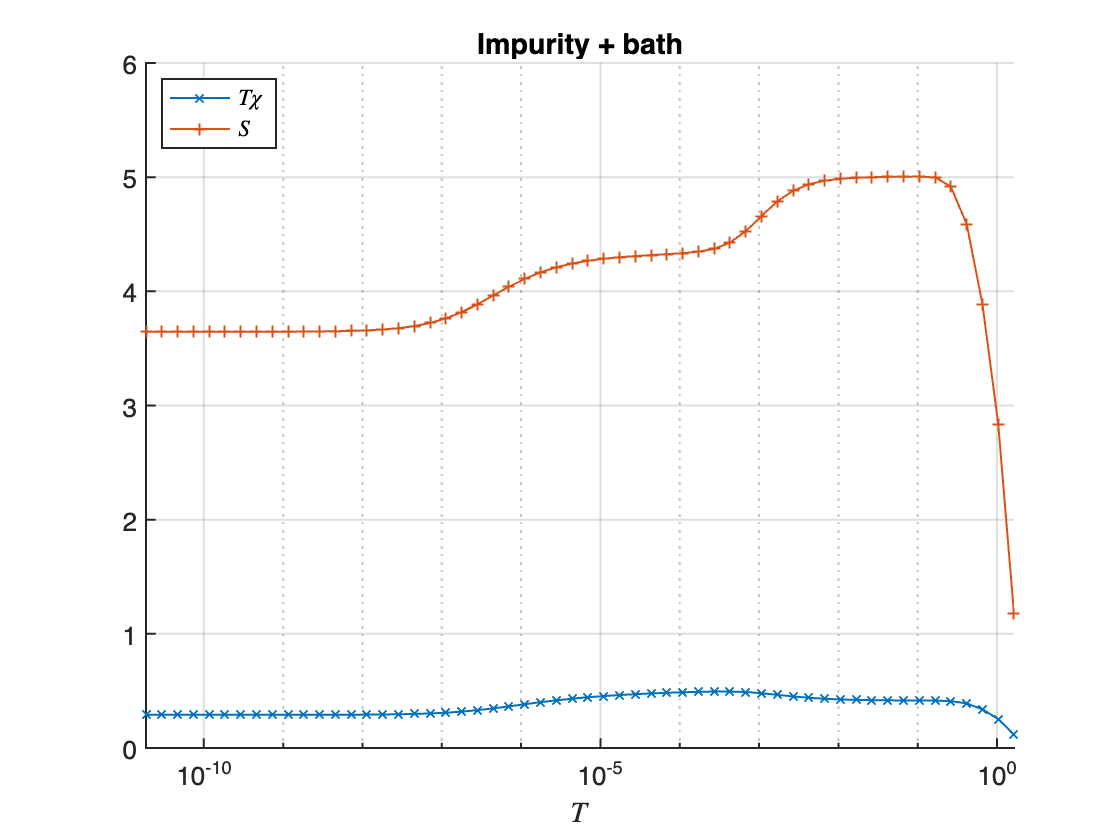

beta0 = 1; % parameter to define temperature values
[T,Tchi,Sent] = getTDconv_Ex (Inrg,S(:,:,2),beta0);
% temperature T, T * spin susceptibility chi, entropy S

figure;
hold on;
plot(T,Tchi,'LineStyle','-','Marker','x','LineWidth',1);
plot(T,Sent,'LineStyle','-','Marker','+','LineWidth',1);
hold off;
set(gca,'XScale','log','LineWidth',1,'FontSize',13);
legend({'$T \chi$', '$S$'}, ...
    'Interpreter','latex','Location','northwest');
xlabel('$T$','Interpreter','latex');
title('Impurity + bath');
xlim([min(T) max(T)]);
grid on;

## Thermodynamic properties of the bath only

Then we compute the same properties when there is no impurity in the system. The simplest way is to apply large on-site potential to the impurity which effectively empties out the impurity. By using the same functions except for the large on-site potential, the results are given on the same temperature grid.

% "without" impurity
H0_2 = 1e4*sum(NF,3);
% take the impurity level epsd to be far above the band edge (epsd >> 1);
% effectively emptied out
Inrg2 = NRG_IterDiag_Ex (H0_2,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-16 03:28:58 | NRG: start
22-10-16 03:28:58 | #00/55 : NK=4/4, EK=2e+04/2e+04
22-10-16 03:28:58 | #01/55 : NK=16/16, EK=1.932e+04/1.932e+04
22-10-16 03:28:58 | #02/55 : NK=64/64, EK=3.055e+04/3.055e+04
22-10-16 03:28:58 | #03/55 : NK=256/256, EK=4.83e+04/4.83e+04
22-10-16 03:28:58 | #04/55 : NK=328/1024, EK=3.818e+04/7.637e+04
22-10-16 03:28:58 | #05/55 : NK=328/1312, EK=8.523/6.037e+04
22-10-16 03:28:59 | #06/55 : NK=300/1312, EK=9.243/16.78
22-10-16 03:28:59 | #07/55 : NK=328/1200, EK=8.516/15.99
22-10-16 03:28:59 | #08/55 : NK=300/1312, EK=9.238/16.78
22-10-16 03:28:59 | #09/55 : NK=328/1200, EK=8.514/15.99
22-10-16 03:28:59 | #10/55 : NK=300/1312, EK=9.238/16.78
22-10-16 03:29:00 | #11/55 : NK=328/1200, EK=8.514/15.99
22-10-16 03:29:00 | #12/55 : NK=300/1312, EK=9.238/16.78
22-10-16 03:29:00 | #13/55 : NK=328/1200, EK=8.514/15.99
22-10-16 03:29:00 | #14/55 : NK=300/1312, EK=9.238/16.78
22-10-16 03:29:01 | #15/55 : NK=328/1200, EK=8.514/15.99
22-10-16 03:29:01 | #16/55 : NK=300

[~,Tchi2,Sent2] = getTDconv_Ex (Inrg2,S(:,:,2),beta0);

Plot the obtained data. The values show simpler temperature dependence than those of the whole impurity system.

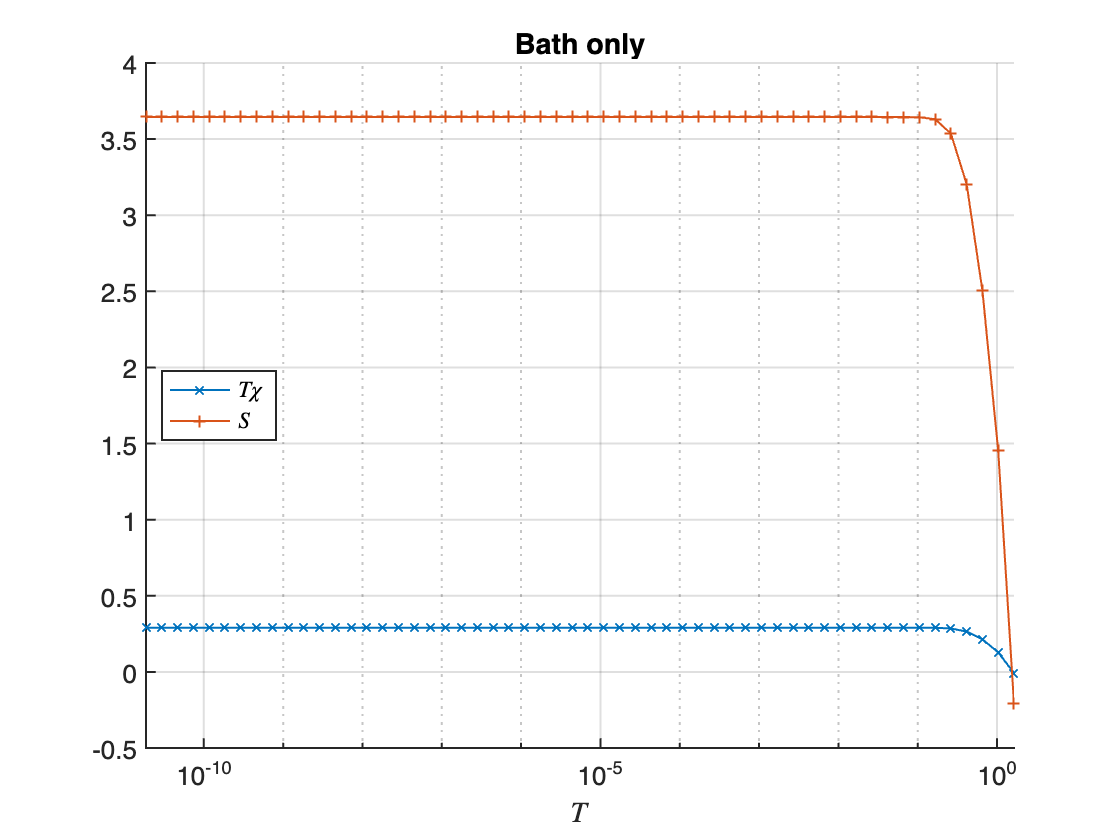

figure;
hold on;
plot(T,Tchi2,'LineStyle','-','Marker','x','LineWidth',1);
plot(T,Sent2,'LineStyle','-','Marker','+','LineWidth',1);
hold off;
set(gca,'XScale','log','LineWidth',1,'FontSize',13);
legend({'$T \chi$', '$S$'}, ...
    'Interpreter','latex','Location','west');
xlabel('$T$','Interpreter','latex');
title('Bath only');
xlim([min(T) max(T)]);
grid on;

## Impurity contribution

Subtract the values for the bath only from those for the whole impurity model, to obtain the impurity contribution.

% impurity contribution to the spin susceptibility * temperature
Tchi_imp = Tchi - Tchi2; 
% impurity contribution to the entropy
Sent_imp = Sent - Sent2;

The specific heat can be obtained by differentiating the entropy,


$$C = T \frac{\partial S}{\partial T} = \frac{\partial S}{\partial (\ln T)} .$$


logT = log(T);
% impurity contribution to the specific heat C = T* dS/dT = dS / d(log T)
% numerical differentiation
C_imp = interp1((logT(1:end-1)+logT(2:end))/2, ...
    diff(Sent_imp)./diff(logT),logT,'linear','extrap');

Then we obtain the Sommerfeld–Wilson ratio.

% Sommerfeld-Wilson ratio
WR = (Tchi_imp./C_imp)*(4*(pi^2)/3);

The characteritic temperature scale of the Kondo regime is, literally, the Kondo temperature $T_\mathrm{K}$. The Kondo temperature is the energy scale at which the crossover to the Kondo regime happens. Since the crossover is a smooth change, there are different ways to define the Kondo temperature, which give similar but different values. In this analysis, we use the formula given by the Bethe ansatz solution,


$$T_\mathrm{K} = 0.4107 \sqrt{\frac{U\Delta_0}{2}} \exp \left( - \frac{\pi U}{8 \Delta_0} + \frac{\pi \Delta_0}{2 U} \right)$$


Refer to Eq. (6.109) and the following text in Hewson1993 [A. C. Hewson, *The Kondo Problem to Heavy Fermions*, Cambridge University Press (1993)] for the details of the formula.

% Kondo temperature from the Bethe ansatz
TK = 0.4107*sqrt(U*Delta0/2)*exp(-pi*U/8/Delta0 + pi*Delta0/2/U);
disp(TK);

   5.9827e-07



Plot the result.

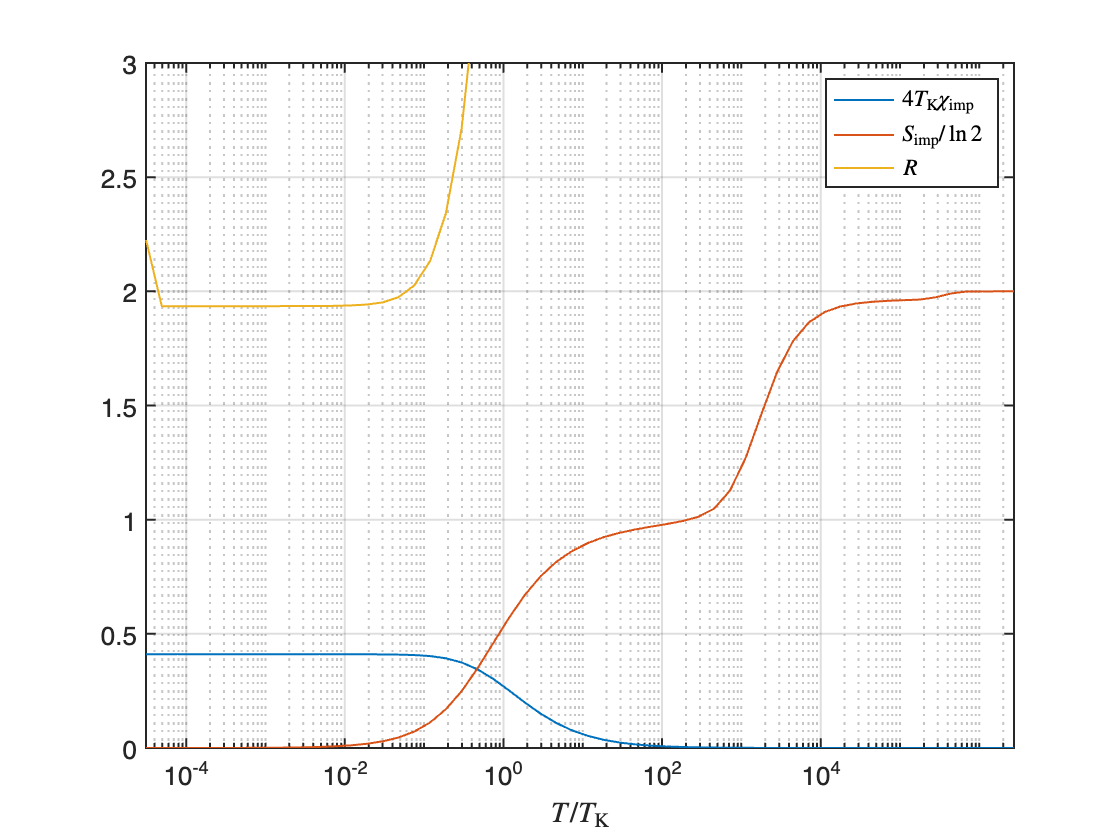

figure;
semilogx(T/TK,(Tchi_imp./T)*(4*TK), ...
    T/TK,Sent_imp/log(2), ...
    T/TK,WR,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13,'XTick',10.^(-4:2:4));
xlabel('$T / T_\mathrm{K}$','Interpreter','latex');
legend({'$4 T_\mathrm{K} \chi_\mathrm{imp}$'; ...
    '$S_\mathrm{imp} / \ln 2$'; ...
    '$R$'}, ...
    'Interpreter','latex','Location','northeast');
ylim([0 3]);
xlim([min(T) max(T)]/TK);
grid on;

At $T \ll T_\mathrm{K}$, the Sommerfeld–Wilson ratio $R$ becomes 2, up to 3% error. The impurity contribution to the entropy $S_\mathrm{imp}$ is $\ln 4$ at high temperature $T \gg U$, then decreases to $\ln 2$, and then finally vanishes at temperatures $T \ll T_\mathrm{K}$. These values indeed represent the nature of different fixed-point regimes:

- Free orbital regime: At $T \gg U$, all four states of the impurity can be populated, so the presence of the impurity adds up $\ln 4$ to the entropy.

- Local moment regime: At $T_\mathrm{K} \ll T \ll U$, only the singly occupied states of the impurity can be populated. So the impurity contribution is $\ln 2$, for two impurity states of $S_{d,z} = \pm 1/2$.

- Strong coupling regime: At $T \ll T_\mathrm{K}$, the impurity spin and the bath form the Kondo singlet. The impurity state is locked into the bath state; the impurity and the bath are quantum entangled. Thus there is no additional entropy by the presence of the impurity.

There are a few technical remarks.

- The values of $T\chi$ and $S$, for the whole impurity system and for the bath only, depend on the choice of $\beta_0$. However, their subtractions $T\chi_\mathrm{imp}$ and $S_\mathrm{imp}$ do not change much with changing $\beta_0$. (**Quick exercise:** try out different values of $\beta_0$.)

- There is a kink in the curve of the Sommerfeld–Wilson ratio at the lowest temperatures ($T \sim 10^{-5} T_\mathrm{K}$). This is a numerical noise. The Sommerfeld–Wilson ratio at such temperatures is given by the ratio between two small values, and each small value is given by the subtraction of two large values (one for the whole impurity and the other for the bath only). For example, `Tchi(end)` and `Tchi2(end)` are $O(0.1)$, but their difference, `Tchi_imp(end)` is just $O(10^{-6})$. That's why we have performed the post-processing of the Wilson chain paramers above.

## Exercise (b): Single-impurity Kondo model

Compute the theremodynamic properties for the single-impurity Kondo model, for the value of $J = 8\Delta_0 D/\pi U$, considering the same values of $\Delta_0$ and $U$ used in the above demonstration. Compare your result with Fig. 5 of Bulla2008. Also compare with the SIAM result of $4T_\mathrm{K} \chi_\mathrm{imp}$, $S_\mathrm{imp}/\ln 2$, and $R$, shown in the above demonstration.